## Hydrological model. 

*Implement the hydrological model on the 6-year-long series of precipitation and discharge.*

clear 
close


%% Load data
load area_rating_curve.txt
load kc.txt
load P.txt
load Q_obs.txt
load temperature.txt

Nyears=length(Q_obs)/(365*24);
day_month=[31 28 31 30 31 30 31 31 30 31 30 31]; %"day_month": number of days for each month
hour_month=day_month*24;
month_end=cumsum(day_month);                     %"month_end": last day of each month
month_start=month_end-day_month+1;               %"month_start": first day of each month
month_end_hour=cumsum(hour_month);                  
month_start_hour=month_end_hour-hour_month+1;
Q_hour_year=reshape(Q_obs,365*24,Nyears);
P_hour_year=reshape(P,365*24,Nyears);

%%Parameters for the hydrological model
sw = 0.25;      %[-] Wilting point
s1 = 0.4;       %[-] Soil moisture stress threshold
n = 0.3;        %[-] Porosity
Q_b = 7;        %[m^3/s] Baseflow
t_sup = 22;     %[h] Mean superficial residence time
A = 4000;       %[km^2] Catchment area
phi = 38;       %[°] Latitude 

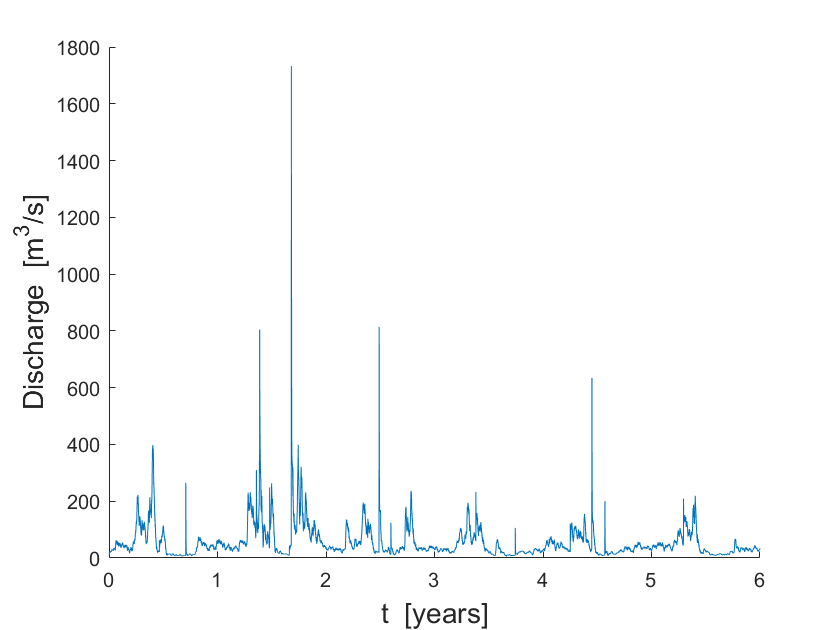

%% Plot discharge time series

figure(1)                                          %create a new figure
plot((1:length(Q_obs))/(365*24),Q_obs);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Discharge  [m^{3}/s]','FONTSIZE',14)       %insert label y axis
box off 

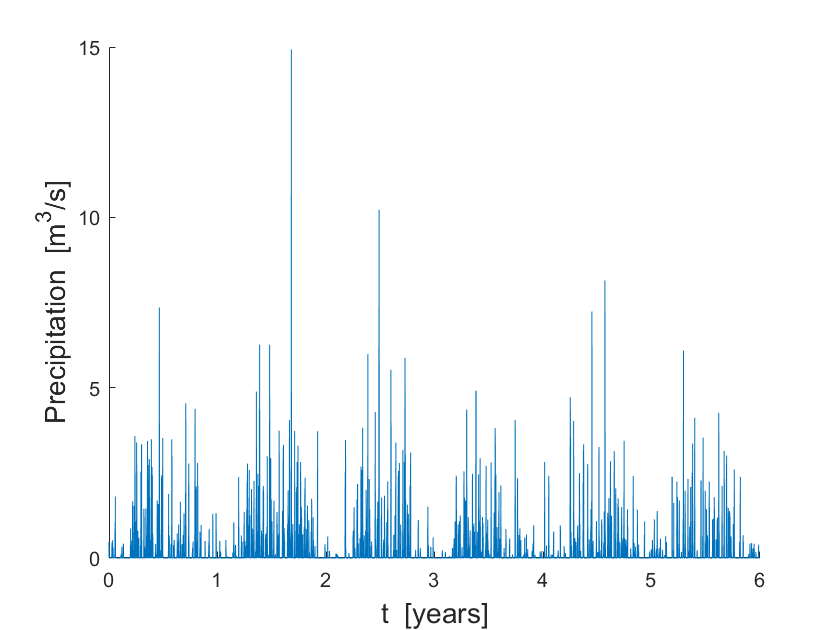

%% Plot precipitation time series

figure(2)                                          %create a new figure
plot((1:length(P))/(365*24),P);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Precipitation  [m^{3}/s]','FONTSIZE',14)   %insert label y axis
box off

### 1.Compute reference crop evapotranspiration ET0 (potential evapotranspiration) through the Thornthwaite equation 

I= sum((temperature./5).^(1.514)) ; %heat index
a= 6.75*(10^(-7))*(I^3) - 7.71*(10^(-5))*(I^2) + 1.79*(10^(-2))*I + 0.49; %experimental exponent
D = 1:365;
delta=0.409*sin(2*pi*D/365-1.39);
w_s = acos(-tan(phi*pi/180)*tan(delta));
N_D = 24*w_s/pi; %number of daylight hours of day D
N_M =zeros(12,1); % mean daylight hours of month m


for i=1:12
    N_M(i) = sum((N_D(month_start(i):month_end(i))))/(day_month(i)); 
end

ET_0 = (16/12)*N_M.*((10*temperature/I).^a); % [mm/unit area]

### 2. Attribute arbitrary values to the parameters K_sat, c, t_sub, z.

% Hydrological model: to be calibrated

K_sat = 10e-5;      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5
c = 20;              %[-] Exponent for power-law relation L(s)  1<c<20
z = 2000;              %[L] Root zone depth 1<z<2000 [mm]
t_sub = 200;          %[T] Mean sub-superficial residence time 1<t_sub<400

### 3. Use an Euler explicit scheme to integrate the system of equations at hourly scale

% Settings
s = zeros(length(Q_obs),1);    % saturation vector
s(1) = 0.5;                    % initial arbitrary value

Vsup = zeros(length(Q_obs),1);  % superficial stored volume vector
Vsup(1) = 0;                  % initial arbitrary value

Vsub = zeros(length(Q_obs),1); %  sub-superficial stored volume vector
Vsub(1) = 0;                  % initial arbitrary value

N_hours_per_year = 365*24;  %number of hours per year
ET_hour_year = zeros(size(Q_hour_year)); 
L = zeros(length(Q_obs),1);

% Infiltration
K_sat_vect = ones(length(P),1)*K_sat;  % K_sat vector to compare with precipitation
I = min(P,K_sat_vect);
I_hour_year = reshape(I,N_hours_per_year,Nyears); %reshaping infiltration vector into matrix with hours in lines and years in columns

% Runoff
R = P-I;
R_hour_year = reshape(R,N_hours_per_year,Nyears); %reshaping runoff vector into matrix with hours in lines and years in columns



for y=1:Nyears
    for m=1:12
        for h=month_start_hour(m):month_end_hour(m)
            t=(y-1)*N_hours_per_year+h; 
            if s(t)<=sw && s(t)>=0
                ET_hour_year(h,y)= 0;
            elseif s(t)<=s1 && s(t)>sw
                ET_hour_year(h,y)= kc(m)*ET_0(m)*((s(t)-sw)/(s1-sw));
            elseif s(t)<=1 && s(t)>s1
                ET_hour_year(h,y)= kc(m)*ET_0(m);
            end
            L(t)=K_sat*(s(t)^c);
            s(t+1)=s(t)+((I(t)-ET_hour_year(h,y)-L(t))*(1/(n*z)));
            Vsup(t+1)=Vsup(t)+R(t)-((t_sup^(-1))*Vsup(t));
            Vsub(t+1)=Vsub(t)+L(t)-((t_sub^(-1))*Vsub(t));
        end
    end
end


ET=reshape(ET_hour_year,[],1);
qsup=(t_sup^(-1)).*Vsup;
qsub=(t_sub^(-1)).*Vsub;
Qsup=A*qsup;
Qsub=A*qsub;

### 4. Test the mass balance of your system in order to ensure a correct implementation.

doTest=1;
dt=1;

%compute total discharge Q
if doTest % if doTest=1, check mass balance
    P_tot=sum(P)*dt;
    R_tot=sum(R)*dt;
    L_tot=sum(L)*dt;
    ET_tot=sum(ET)*dt;
    %"testS" balance for the root zone (input/output). testS = 1: necessary (but not sufficient)
    %condition for the implementation to be correct
    testS=P_tot/(ET_tot+R_tot+L_tot+n*z*(s(end)-s(1)))

    %"testQ" balance for the whole system (input/output). testQ = 1: necessary (but not sufficient)
    %condition for the implementation to be correct
    testQ=sum(P-ET)/(sum(qsup+qsub)+n*z*(s(end)-s(1))+Vsup(end)+Vsub(end))
end

testS = 1.0000

testQ = 1.0000

### 5. Evaluate the goodness of fit of the chosen parameter set by calculating the Nash-Sutcliffe index NS.


Q_mod = Qsub+Qsup+Q_b;
Q_mod = Q_mod(1:52560,1);
NS = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))

NS = -112.2871

## Model calibration

Find the set of parameters {Ksat, c, tsub, z} that maximizes the Nash-Sutcliffe index. Use a simulated annealing strategy in order to find the parameter set that maximizes NS.

### 1. Define a functional form for the temperature

### 2. Attribute arbitrary values to the parameters Ksat, c, tsub, z. Run the hydrological model and evaluate NSold.

K_sat = 10e-5;      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5
c = 20;              %[-] Exponent for power-law relation L(s)  1<c<20
z = 2000;              %[L] Root zone depth 1<z<2000 [mm]
t_sub = 200;          %[T] Mean sub-superficial residence time 1<t_sub<400

delta = [K_sat, c, z, t_sub];
ranges = [9.9e-05,19,1999,399];
upper_lim = [10e-5,20,2000,400];
lower_lim = [10e-7,1,1,1];
sigma = 5/100;
cr = 1/1200;
mode=0;
Q_mod = hydro_model(P, Q_obs, ET_0, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A, phi,mode);
Q_mod = Q_mod(1:52560,1);
NS_old = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)));



### 3. Select a new parameter set by drawing from a truncated normal distribution cen�tered in the previous parameter set (use function TruncNormRnd.m)

delta_old=delta;
delta_new=delta;


i = 1

i = 1

while true
    for i=1:length(delta)
        delta_new(i)=TruncNormRnd(delta_old(i),sigma,lower_lim(i),upper_lim(i));
    end
    Q_mod = hydro_model(P, Q_obs, ET_0, kc, delta_new(1),delta_new(2), delta_new(4), t_sup, delta_new(3), sw, s1, n, Q_b, A, phi,mode);
    Q_mod = Q_mod(1:52560,1);
    NS_new = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)));
    
    if NS_new>NS_old
        delta_old = delta_new;
        NS_old = NS_new;
    else
        r = rand;
        if r<exp((NS_new-NS_old)/t_sa(cr,i))
            NS_old = NS_new;
        end
    end
    if NS_new >=0.85
        break
    end
    i=i+1;
end



